# 预处理

%Dl归一化
Norm=sqrt(sum(Dl.^2));
Norm_Dl=Dl/Norm;    
img=imread("input.bmp");
% 初始值设置
patch_size=sqrt(size(Dh,1));
overleap=2;
lambda=0.2;
img=imread("input.bmp");
img_ycbcr=rgb2ycbcr(img);
img_y=img_ycbcr(:,:,1);
img_cb=img_ycbcr(:,:,2);
img_cr=img_ycbcr(:,:,3);



## 插值变尺寸

img_y_2=imresize(img_y,[1024,1024]);
img_h_ycbcr=zeros([size(img_y_2),3]);

## 提取低分辨率图特征

kernel1=[-1 0 1];
kernel2=[-1 0 1]';
kernel3=[1 0 -2 0 1];
kernel4=[1 0 -2 0 1]';
[nrow,ncol]=size(img_y_2);
[h,w]=size(img_y_2);
features=zeros([nrow,ncol,4]);
features(:,:,1)=conv2(img_y_2,kernel1,'same');
features(:,:,2)=conv2(img_y_2,kernel2,'same');
features(:,:,3)=conv2(img_y_2,kernel3,'same');
features(:,:,4)=conv2(img_y_2,kernel4,'same');
ximg = zeros(size(img_y_2));
cntMat = zeros(size(img_y_2));

## 对每个特征块求最优高分辨率块(循环）

gridx = 3:patch_size - overleap : w-patch_size-2;    %m每个图像块的中心x坐标，以及块数
gridx = [gridx, w-patch_size-2];
gridy = 3:patch_size - overleap : h-patch_size-2;    %m每个图像块的中心y坐标，以及块数
gridy = [gridy, h-patch_size-2];
A = Dl'*Dl;
cnt = 0;
for i = 1:length(gridx)
    for j = 1:length(gridy)
        cnt = cnt+1;        %flag次数
        xx = gridx(i);
        yy = gridy(j);
        
        mPatch = img_y_2(yy:yy+patch_size-1, xx:xx+patch_size-1);   %原图像的patch
        m = mean(mPatch(:));    %计算m
        mPatch = mPatch(:) - m;
        mNorm = sqrt(sum(mPatch.^2));       %归一化！
        
        mPatchFea = features(yy:yy+patch_size-1, xx:xx+patch_size-1, :);    
        mPatchFea = mPatchFea(:);   %展开为一维向量
        mfNorm = sqrt(sum(mPatchFea.^2));  
        if mfNorm > 1    %求解Fy
            Fy = mPatchFea./mfNorm;
        else
            Fy = mPatchFea;
        end
        b = -Norm_Dl'*Fy;
        a = L1QP(lambda, A, b);
        xpatch=Dh*a;
        xpatch=rescale(xpatch,mNorm);
        xpatch = reshape(xpatch, [patch_size, patch_size]);
        xpatch=xpatch+m;
        ximg(yy:yy+patch_size-1, xx:xx+patch_size-1) = ximg(yy:yy+patch_size-1, xx:xx+patch_size-1) + xpatch;
        cntMat(yy:yy+patch_size-1, xx:xx+patch_size-1) = cntMat(yy:yy+patch_size-1, xx:xx+patch_size-1) + 1;
    end
end
%flag 小于 1 的使其等于 1，然后 X./flag(解决过亮问题)
idx = (cntMat < 1);
ximg(idx) = img_y_2(idx);

cntMat(idx) = 1;
ximg = ximg./cntMat;
%ximg = uint8(ximg);

## 重建后

img_h_y=ximg

img_h_y =   132.0000  132.0000  132.0000  132.0000  132.0000  132.0000  132.0000  132.0000  131.0000  131.0000  131.0000  131.0000  131.0000  131.0000  131.0000  131.0000  131.0000  131.0000  130.0000  130.0000  130.0000  129.0000  128.0000  128.0000  127.0000  126.0000  125.0000  124.0000  124.0000  123.0000  122.0000  122.0000  121.0000  120.0000  119.0000  119.0000  117.0000  116.0000  115.0000  114.0000  112.0000  110.0000  109.0000  107.0000  105.0000  103.0000  100.0000   98.0000   95.0000   93.0000
  132.0000  132.0000  132.0000  132.0000  132.0000  132.0000  132.0000  132.0000  131.0000  131.0000  131.0000  131.0000  131.0000  131.0000  131.0000  131.0000  131.0000  131.0000  130.0000  130.0000  130.0000  129.0000  128.0000  128.0000  127.0000  126.0000  125.0000  124.0000  124.0000  123.0000  122.0000  122.0000  121.0000  120.0000  119.0000  119.0000  117.0000  116.0000  115.0000  114.0000  112.0000  110.0000  109.0000  107.0000  105.0000  103.0000  100.0000   98.0000   95.000

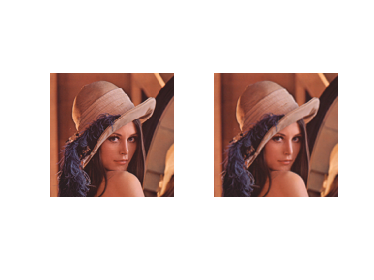

[nrow,ncol]=size(img_h_y);
im_h_cb=imresize(img_cb,[nrow,ncol],'bicubic');
im_h_cr=imresize(img_cr,[nrow,ncol],'bicubic');
img_h_ycbcr(:,:,1)=img_h_y;
img_h_ycbcr(:,:,2)=im_h_cb;
img_h_ycbcr(:,:,3)=im_h_cr;
im_h=ycbcr2rgb(uint8(img_h_ycbcr));
figure;
subplot(1,2,1)
imshow(img)
subplot(1,2,2)
imshow(im_h)